[x, y] = meshgrid(-2:0.07:3, -3.7:0.07:1.3);

obstacleScale = 1;

v = - obstacleScale*log(sqrt((x+0.25).^2 + (y+1).^2)) - obstacleScale*log(sqrt((x-1).^2 + (y+0.7).^2))- obstacleScale*log(sqrt((x-1.41).^2 + (y+2).^2)) + 10*log(sqrt((x-0.75).^2 + (y+2.5).^2));

wallScale = 0.25;

for a = -1.5:0.1:2.5
    v = v-wallScale*(log(sqrt((x-a).^2+(y-1).^2)) + log(sqrt((x-a).^2 + (y+3.37).^2)));
end
for a = -3.37:0.1:1
    v = v-wallScale*(log(sqrt((x-2.5).^2+(y-a).^2)) + log(sqrt((x+1.5).^2 + (y-a).^2)));
end
[FX, FY] = gradient(v);

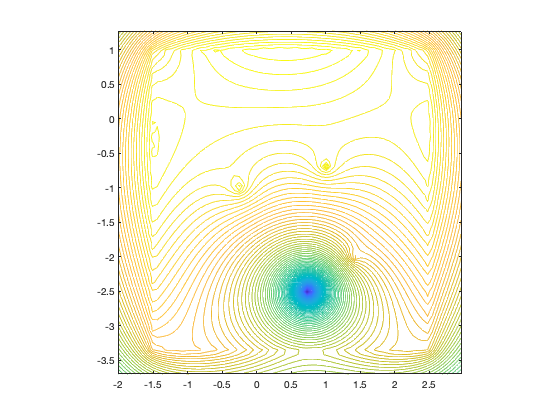

contour(x, y, v, 100)
axis square

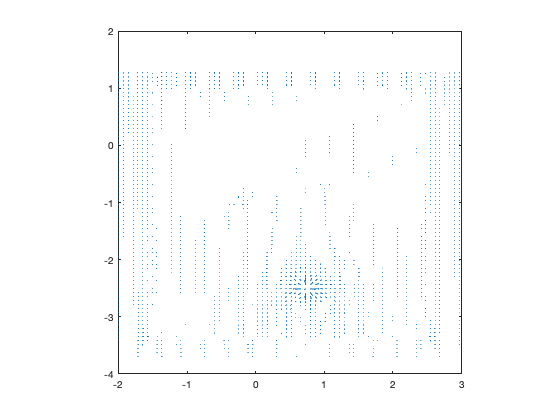

quiver(x, y, FX, FY)
axis square

v;